clear;
n=2;
coordinate=sym("u%d",[n,1]);
X=[coordinate(1)
    coordinate(2)
    sqrt(coordinate(1)^2+coordinate(2)^2)];
uinterval=[-5 5];
vinterval=[-5,5];
hh=hjs("n",n,"coordinate",coordinate,"X",X);

hh();

hh.curvature_tensor();
hh.g

$$ans = \left(\begin{array}{cc} \frac{{u_{1}}^{2}}{{u_{1}}^{2}+{u_{2}}^{2}}+1 & \frac{u_{1}\,u_{2}}{{u_{1}}^{2}+{u_{2}}^{2}}\\ \frac{u_{1}\,u_{2}}{{u_{1}}^{2}+{u_{2}}^{2}} & \frac{{u_{2}}^{2}}{{u_{1}}^{2}+{u_{2}}^{2}}+1 \end{array}\right)$$

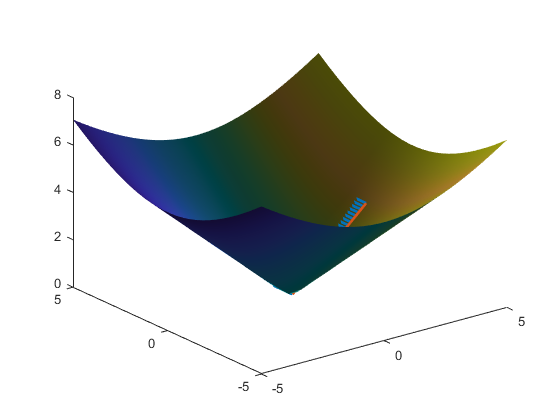

hh.drawmesh(uinterval,vinterval,0);
hold on;
syms t;
u(t)=[0.1+t;0];
 hh.scale=0;
hh.parallel_transport(u,[0;3],[0,1],30);

figure;
hh.Gauss_curvature

$$ans = 0$$

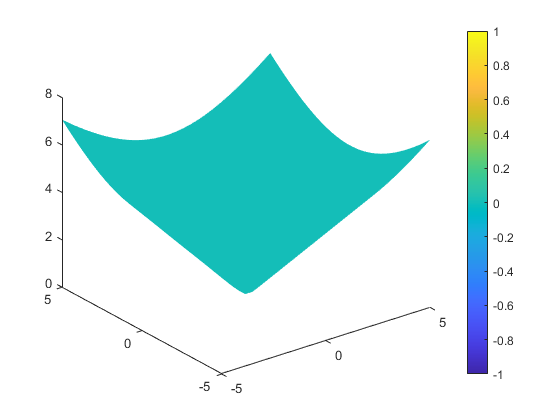

hh.drawmesh(uinterval,vinterval,1);

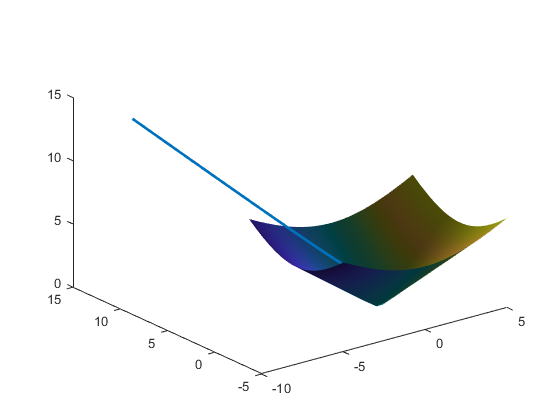

figure;
hh.drawmesh(uinterval,vinterval,0);
hold on;
hh.geodesic([0,200],[0.1, 0, -0.1, 1],100);